# Chap 2: Linear regression with least square estimate

A. Rey, MSE, MA-StatDig, 02.2022

clear;

## Exercice 2.1 Elipses

### Description

We collect a dataset of measurements (for exemple positions) and they are plotted in a 2 axis graph shown bellow:

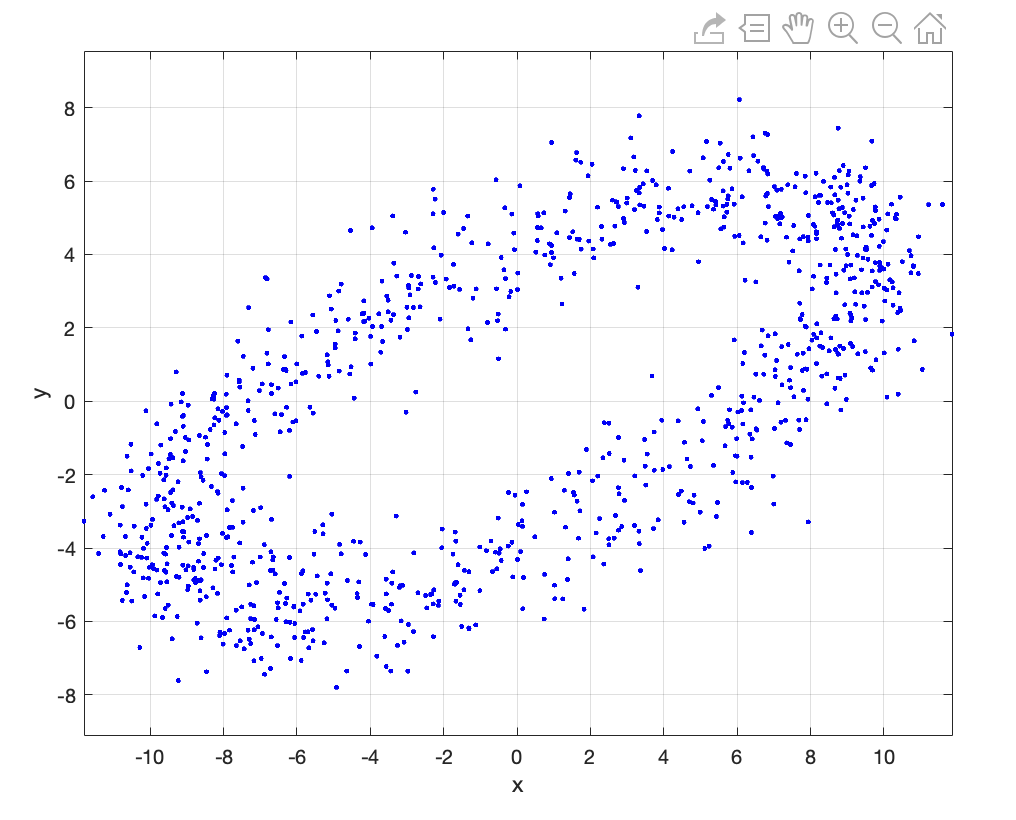

Figure 1

The goal is to find the best Elipse aproximation with the minimum of the $L_2$ norm. and then plot it like in the figure 2:

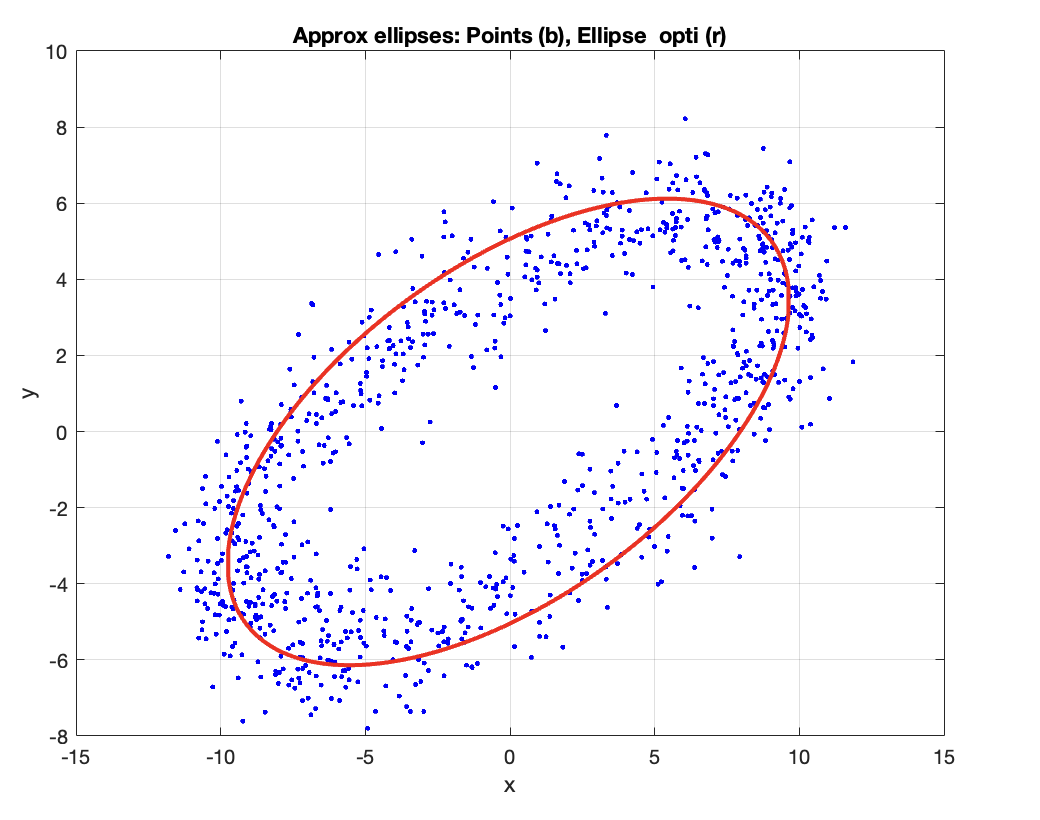

Figure 2

### Theory

The ellipse equation is given by:

$ax^2 + by^2 + cx + dy + exy = 1$     (1)

the constants values $a,b,c,d,e$ are  the parameters to be found, in this case they are the unknowns of the problem to solve. We need only 5 points $P(x_i,y_i)$ to determine the constants $a,b,c,d,e$, but here we want to find the best approximation that minimize the $L_2$ norm of  the error between the points $P(x_i,y_i)$ and the best ellipse approximation.

For each point $P_i = P(x_i,y_i)$ we could write the equation above for $N$ points we have the overdetermined system of equations with $N$ equations and 5 unknowns.

### Data Import and plot				

First import the data from the file `EllipseData.mat`, the points are in the matrix `Pi`, the column number is the point number $i$ the first row contain the $x_i$ values and the second row contans the $y_i$ values.

Next plot the points in a graph like this shown in figure 1.

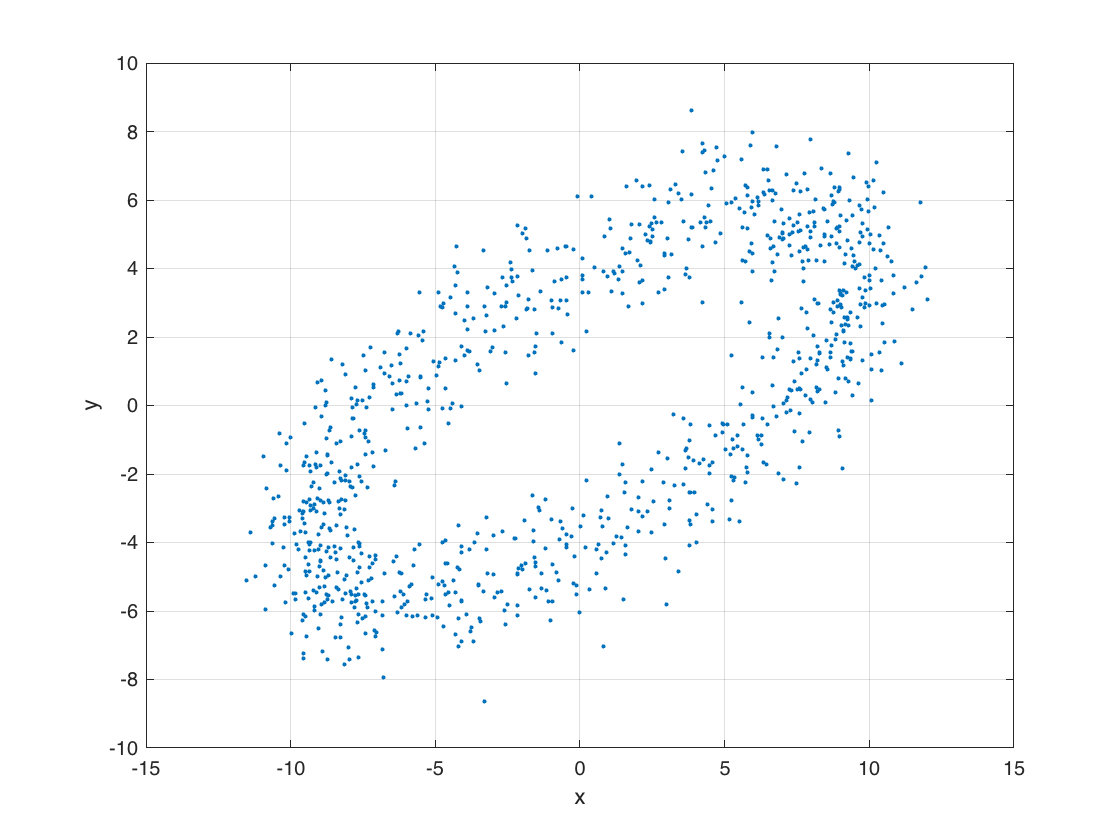

load('ex21_Ellipse_data.mat');
xi = Pi(1,:)';
yi = Pi(2,:)';
N = length(xi);

figure
    plot(xi, yi, '.')
    xlabel('x')
    ylabel('y')
    grid;

### Compute the parameters for the best ellipse

Build the matrix $A$ and the vector $b$ representing the system of $N$ equations like the equation (1):

To find the best parameters  we need to solve the over-determined system:

$A\Theta = b$     (2)

It is no solution, that satisfies all the conditions (all points) so we could only find an approximation, solving eq (2) by pseudo inverse will give:

$\hat{\Theta} = (A^TA)^{-1}A^Tb$     (3)

A = [xi.^2, yi.^2, xi, yi, xi.*yi];
b = ones(N, 1);
%Thetahat = inv(A'*A)*A'*b % use below one to avoid warning
Thetahat = (A'*A)\A' * b

Thetahat =     0.0162
    0.0395
   -0.0019
    0.0003
   -0.0296


### Compute the best ellipse points

With those parameters it is possible to plot the approximation of the Elipse that fit the measurement points $P_i$ but it is not trivial because $y$ coordinates depends of $x$ coordinates as shown by the ellipse equation (1) so we need compute for each possible $x$ (in the same range than in the dataset) the corresponding $y$ on the best elipse given by the approximation parameters. From the equation (1) we need to solve $\hat{y} = f(x,\hat{\Theta})$ and this is a second order equation with 2, 1 or 0 real possible values of $y$ for each $x$.

Let's re-write the eq (1) like this:

$by^2 + (d+ex)y + (ax^2+cx-1) = 0$ we need to exprime $y$ and to simplify the notation we call $V = d + ex$ and $W = (ax^2+bx-1)$ and $Z=b$ 

the equation would be $Zy^2 +Vy + W = 0$ so y is find by solving this second order equation:

$y = \frac{-V\pm\sqrt{V^2-4ZW}}{2Z}$     (4) 

First create a $x$ vectos with the enough points to plot an Elipse trajectory and with the same span than the $x_i$ values in the data set:

Create the variables $Z$, $V$ and $W$ with the data $x_i$ and the parameters in the vector $\hat{\Theta}$ :

Next compute the $\hat{y_i}$ values by solving (4) for positive and negative case (be careful to not take the non-real values):

x = floor(min(xi)):0.001:max(xi);
% For helping parameters a,b,c,d,e are equal to:
% a = Thetahat(1)
% b = Thetahat(2)
% c = Thetahat(3)
% d = Thetahat(4)
% e = Thetahat(5)

V = Thetahat(4) + Thetahat(5).*x;
W = Thetahat(1).*x.^2 + Thetahat(3).*x - 1;
Z = Thetahat(2);

discriminant = V.^2 - 4.*Z.*W;

x_double = [x(discriminant >= 0), x(discriminant >= 0)];
y = [(-V(discriminant >= 0) + (sqrt(discriminant(discriminant >= 0)))) ./ (2*Z), ...
     (-V(discriminant >= 0) - (sqrt(discriminant(discriminant >= 0)))) ./ (2*Z)];

### Plot the best ellipse

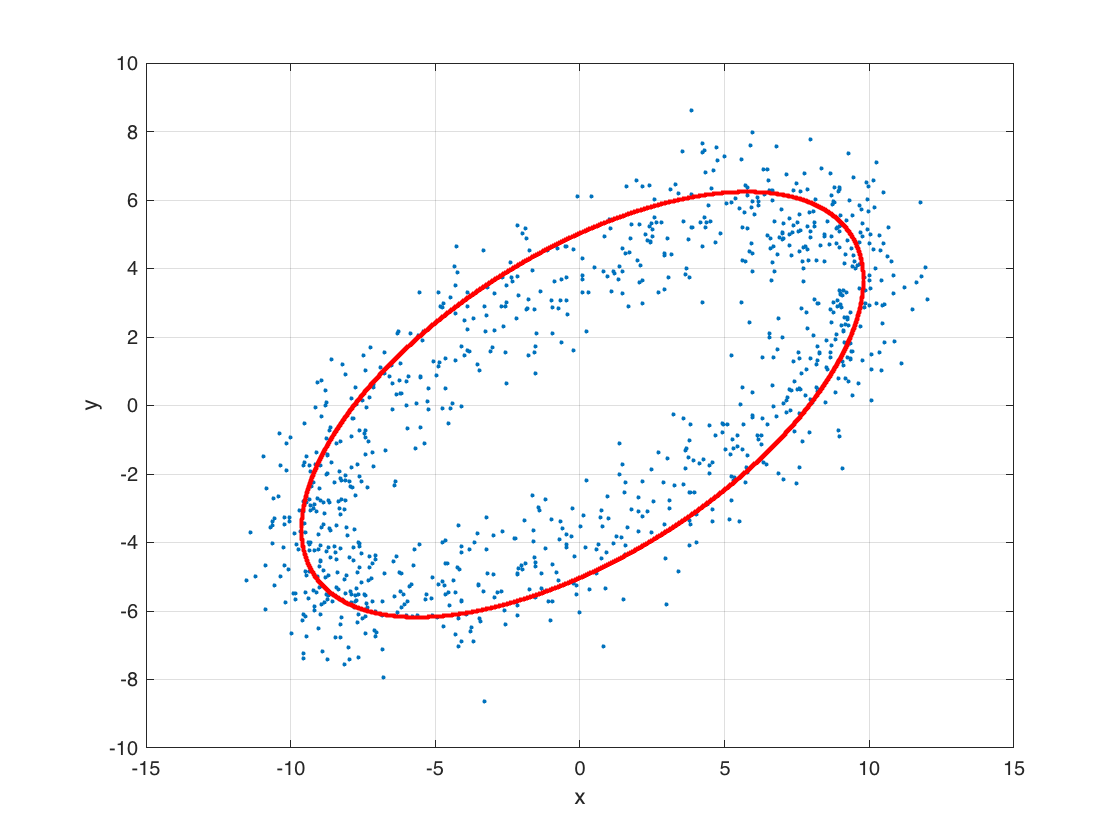

figure
    plot(xi, yi, '.', ...
        x_double, y, '.r');
    xlabel('x')
    ylabel('y')
    grid

### Eigen values and eigen vectors application

To find the principal axis of the Elipse we could compute the covariance matrix of the coordinate points: The Covariance matrix $Cp$ is give by, the size is $2\times 2$ 

$Cp = \frac{1}{N}(P_i^T - m_p)^T(P_i^T-m_T)$ where $m_p$ is the vector of mean values of the rows of $P_i$

We obtain the same result with `cov()` function

mp = mean(Pi, 2)'

mp =    -0.0037   -0.0265


Cp = 1/N .* ((Pi'-mp)' * (Pi'-mp))

Cp =    46.8203   18.5040
   18.5040   17.1023


% check
cov(Pi')

ans =    46.8672   18.5225
   18.5225   17.1194


Now we compute the eigen vectors (colums of `V`) and the eigen values (elements of `D`):

[V,D] = eig(Cp')

V =     0.4324   -0.9017
   -0.9017   -0.4324


D =     8.2297         0
         0   55.6929


% same values as teacher but not sorted in the same way

Eigen vectors must be orthogonals:

if V(:,1)'*V(:,2) == 0
    disp('V(:,1) et V(:,2) sont orthogonaux.')
end

V(:,1) et V(:,2) sont orthogonaux.


Usually we place the eigenvalues and so the eigenvectors, from the bigger to the smaller

V2 = [-V(2,1) V(2,2); -V(2,2) -V(2,1)]

V2 =     0.9017   -0.4324
    0.4324    0.9017


D2 = [D(2,2) 0; 0 D(1,1)]

D2 =    55.6929         0
         0    8.2297


**Remarque intéressante:** Le vecteur propre qui correspond à la valeur propre la plus grande correspond à l'axe le plus large de l'ellipse.